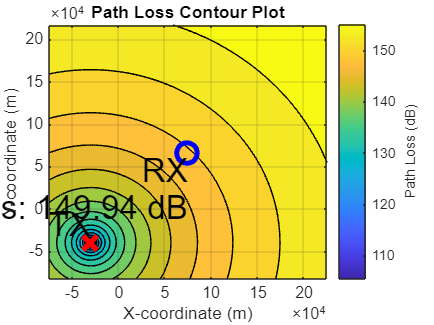

% Define the path loss models
function PL = freeSpacePathLoss(distance, frequency)
    c = 3e8; % Speed of light in m/s
    wavelength = c / frequency; % Wavelength in meters
    PL = 20 * log10((4 * pi * distance) / wavelength); % Path loss in dB
end

% Auxiliary method for creating a path loss contour plot
function create_path_loss_contour(tx_position, rx_position, h_tx, h_rx, range_x, range_y, pl_func, frequency)
    % Create a grid of coordinates for the receiver
    x_range = linspace(rx_position(1) - range_x, rx_position(1) + range_x, 100); % Adjust the range and number of points as needed
    y_range = linspace(rx_position(2) - range_y, rx_position(2) + range_y, 100);
    [X, Y] = meshgrid(x_range, y_range);

    % Calculate distances from transmitter for each point in the grid
    distances = sqrt((X - tx_position(1)).^2 + (Y - tx_position(2)).^2 + (h_rx - h_tx).^2);

    % Calculate path loss values for each distance using the selected path loss function
    path_losses = arrayfun(@(d) pl_func(d, frequency), distances);

    % Create a contour plot
    figure;
    contourf(X, Y, path_losses, 20); % 20 contour levels
    colormap(parula); % Change colormap to 'parula'
    colorbar;
    c = colorbar;
    c.Label.String = 'Path Loss (dB)'; % Add color bar label
    hold on;

    % Add transmitter and receiver positions
    scatter(tx_position(1), tx_position(2), 150, 'red', 'x', 'LineWidth', 3, 'DisplayName', 'Transmitter');
    scatter(rx_position(1), rx_position(2), 150, 'blue', 'o', 'LineWidth', 3, 'DisplayName', 'Receiver');

    % Label positions
    path_loss_rx = pl_func(sqrt((rx_position(1) - tx_position(1))^2 + (rx_position(2) - tx_position(2))^2 + (h_rx - h_tx)^2), frequency);
    text(tx_position(1), tx_position(2), 'TX', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 20);
    text(rx_position(1), rx_position(2), sprintf('RX\nPath Loss: %.2f dB', path_loss_rx), 'VerticalAlignment', ...
        'top', 'HorizontalAlignment', 'right', 'FontSize', 20);

    % Save path loss value to workspace
    assignin('base', 'PL', path_loss_rx);

    % Set axis labels and title
    xlabel('X-coordinate (m)');
    ylabel('Y-coordinate (m)');
    title('Path Loss Contour Plot');
    grid on;
    hold off;
end

% Example usage
tx_position = [-30000, -40000]; % Transmitter position (x, y) in meters
rx_position = [75000, 67000]; % Center of the grid for the receiver positions (x, y) in meters
h_tx = 2; % Transmitter height in meters
h_rx = 500; % Receiver height in meters
range_x = 150000; % Range in meters from the rx_position[0]
range_y = 150000; % Range in meters from the rx_position[1]
frequency = 5000e6; % Frequency in Hz
pl_func = @freeSpacePathLoss; % Path loss function handle

% Create the path loss contour plot
create_path_loss_contour(tx_position, rx_position, h_tx, h_rx, range_x, range_y, pl_func, frequency);